% Definisco i parametri
Ra = 0.06;
La = 0.0006;
f = 1;
J = 100;
km = 3.5;
kv = 3.5;

Ga = 1; %valore iniziale

% Definisco le matrici
A = [0, 1, 0;
     0, -f/J, km/J;
     0, -kv/La, -Ra/La]

A = 	1.0e+03 *

         0    0.0010         0
         0   -0.0000    0.0000
         0   -5.8333   -0.1000


B = [0; 0; Ga/La]

B = 	1.0e+03 *

         0
         0
    1.6667


C = [1, 0, 0]

C =      1     0     0


D = 0

D = 0

% sistema in forma di stato
sys_ol = ss(A,B,C,D)

sys_ol =
 
  A = 
          x1     x2     x3
   x1      0      1      0
   x2      0  -0.01  0.035
   x3      0  -5833   -100
 
  B = 
         u1
   x1     0
   x2     0
   x3  1667
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




% polinomio caratteristico in anello aperto
poly(A)

ans =     1.0000  100.0100  205.1667         0



% autovalori
eig(A)

ans =          0
   -2.0954
  -97.9146


% guadagno, zeri e poli del sistema
[zeros, poles, gain] = zpkdata(sys_ol, 'v')


zeros =

  0×1 empty double column vector



poles =          0
   -2.0954
  -97.9146


gain = 58.3333


disp(zeros) % zeri del sistema
disp(poles) % poli del sistema

         0
   -2.0954
  -97.9146



disp(gain) % guadagno del sistema

   58.3333



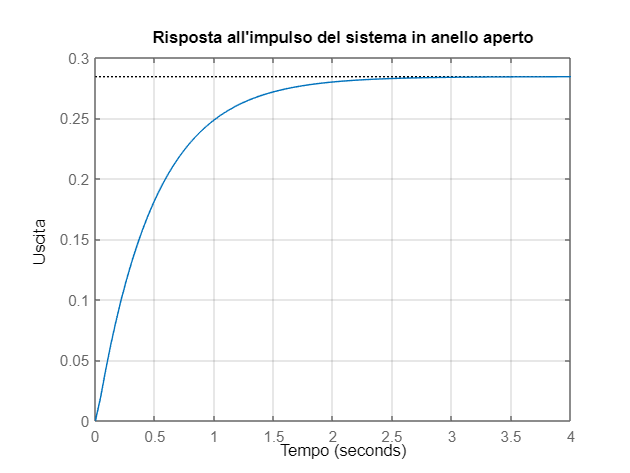

% Visualizzare la risposta all'impulso ed al gradino unitario
figure;
impulse(sys_ol)
title("Risposta all'impulso del sistema in anello aperto")
xlabel("Tempo")
ylabel("Uscita")
grid on;

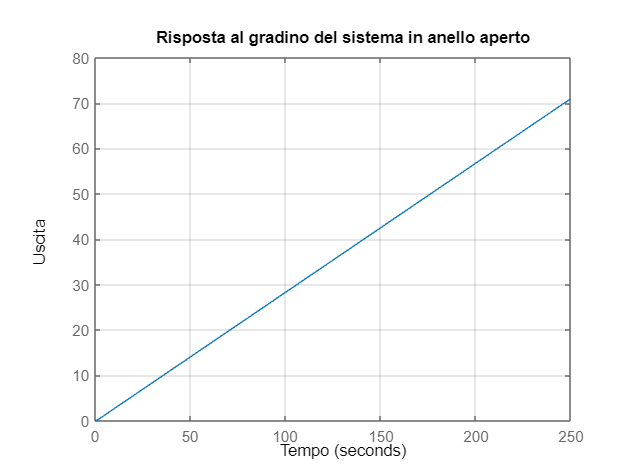


figure;
step(sys_ol)
title("Risposta al gradino del sistema in anello aperto")
xlabel("Tempo")
ylabel("Uscita")
grid on;

% verificare la controllabilità del sistema
if rank(ctrb(A,B)) == length(A)
    disp("sistema completamente controllabile")
else
    disp("sistema non completamente controllabile")
end

sistema completamente controllabile


% retroazione caso 1
p1 = [-10,-sqrt(3)*(1-1j),-sqrt(3)*(1+1j)]

p1 =  -10.0000 + 0.0000i  -1.7321 + 1.7321i  -1.7321 - 1.7321i


k1 = place(A,B,p1)

k1 =     1.0286   -2.8056   -0.0519



% retroazione caso 2
p2 = [-20,-8,-1]

p2 =    -20    -8    -1


k2 = place(A,B,p2)

k2 =     2.7429   -0.2821   -0.0426


% polinomio caratteristico del sistema in anello chiuso
sys_cl1 = ss(A-B*k1,B*k1(1),C,D)

sys_cl1 =
 
  A = 
           x1      x2      x3
   x1       0       1       0
   x2       0   -0.01   0.035
   x3   -1714   -1157  -13.45
 
  B = 
         u1
   x1     0
   x2     0
   x3  1714
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



poly(A-B*k1)

ans =     1.0000   13.4641   40.6410   60.0000



sys_cl2 = ss(A-B*k2,B*k2(1),C,D)

sys_cl2 =
 
  A = 
           x1      x2      x3
   x1       0       1       0
   x2       0   -0.01   0.035
   x3   -4571   -5363  -28.99
 
  B = 
         u1
   x1     0
   x2     0
   x3  4571
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



poly(A-B*k2)

ans =     1.0000   29.0000  188.0000  160.0000


% guadagno in modo da imporre a zero l'errore di posizione in anello chiuso
dcgain(sys_cl1) % deve essere uguale ad 1

ans = 1

dcgain(sys_cl2) % deve essere uguale ad 1

ans = 1

% f.d.t. in anello chiuso, guadagno zeri e poli
[zeros1, poles1, gain1] = zpkdata(sys_cl1, 'v')


zeros1 =

  0×1 empty double column vector



poles1 =  -10.0000 + 0.0000i
  -1.7321 + 1.7321i
  -1.7321 - 1.7321i


gain1 = 60.0000


[zeros2, poles2, gain2] = zpkdata(sys_cl2, 'v')


zeros2 =

  0×1 empty double column vector



poles2 =   -20.0000
   -1.0000
   -8.0000


gain2 = 160.0000

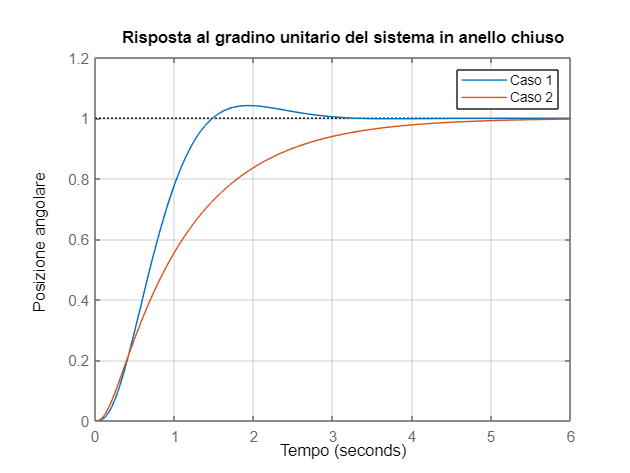

% visualizzare e commentare la risposta al gradino unitario in anello chiuso, confrontando i due casi
figure;
step(sys_cl1, sys_cl2)
title("Risposta al gradino unitario del sistema in anello chiuso")
xlabel("Tempo")
ylabel("Posizione angolare") 
legend("Caso 1", "Caso 2")
grid on;